function EEGHandClassifier_FBCSP()

EEG Hand Movement Classifier — 2-Channel FBCSP + LDA 

    % --- CONSTANTS ---
    FS            = 2000;         % Sampling frequency (Hz)
    
    C3_COL        = 1;            
    C4_COL        = 2;            
    LABEL_COL     = 3;            
    
    % FILTER BANK DEFINITION (Mu and Beta sub-bands)
    FB_BANDS      = [8 12; 12 16; 16 20; 20 24; 24 30]; 
    BP_ORDER      = 8;            % Butterworth filter order
    
    WIN_SAMPLES   = 1000;         
    N_CSP         = 2;            % Number of CSP components (max 2 for 2-channel)
    LABEL_PURITY  = 0.80;         
    
    LABEL_LEFT    = -1;
    LABEL_RIGHT   = +1;
    LABEL_REST    = 0;


DATA LOADING BLOCK

    disp('Loading data into memory...')
    
    % --- TEST SET (a1 / b1) ---
    a3 = load("D:\BCI_DSP\bci_testing\24_attempt3.txt");
    b3 = load("C:\Users\DELL\OneDrive\Desktop\BCI\experiment_data (4).txt");
    
    % --- CALIBRATION SETS ---
    a4 = load("D:\BCI_DSP\bci_testing\24_attempt4.txt");
    b4 = load("C:\Users\DELL\OneDrive\Desktop\BCI\experiment_data (5).txt");
    
    a1 = load("D:\BCI_DSP\bci_testing\24_attempt1.txt");
    b1 = load("C:\Users\DELL\OneDrive\Desktop\BCI\experiment_data.txt");
    a2 = load("D:\BCI_DSP\bci_testing\24_attempt2.txt");
    b2 = load("C:\Users\DELL\OneDrive\Desktop\BCI\experiment_data (1).txt");

    a5 = load("D:\BCI_DSP\bci_testing\24_attempt5.txt");
    b5 = load("C:\Users\DELL\OneDrive\Desktop\BCI\experiment_data (4).txt");
    % 
    % a6 = load("D:\BCI_DSP\bci_testing\24_attempt6.txt");
    % b6 = load("C:\Users\DELL\OneDrive\Desktop\BCI\experiment_data (5).txt");

    
    
    disp('Aligning dimensions (truncating mismatched lengths)...')
    calib_1 = align_data(a1, b1);
    calib_2 = align_data(a2, b2);
    calib_3 = align_data(a3, b3);
    calib_4 = align_data(a4, b4);
    %calib_5 = align_data(a5, b5);
    calib_data = {calib_1, calib_2,calib_3,calib_4}; 
    test_data = align_data(a5, b5); 


PIPELINE EXECUTION

    disp('Starting Training Pipeline (FBCSP)...')
    model = train_classifier_fbcsp(calib_data, FS, C3_COL, C4_COL, LABEL_COL, ...
                                   FB_BANDS, BP_ORDER, WIN_SAMPLES, N_CSP, ...
                                   LABEL_PURITY, LABEL_LEFT, LABEL_RIGHT, LABEL_REST);
                         
    disp('Starting Prediction Pipeline (Optimized FBCSP)...')
    eeg_raw_test = test_data(:, [C3_COL, C4_COL]); 
    preds = predict_continuous_fbcsp(model, eeg_raw_test, FS, FB_BANDS, BP_ORDER, ...
                                     WIN_SAMPLES, LABEL_REST);
                           
    save_predictions(preds, FS, 'test_predictions_fbcsp.csv', LABEL_LEFT, LABEL_RIGHT, LABEL_REST);
    disp('Pipeline Complete!')
end

HELPER: SAFE DATA ALIGNMENT

function aligned_matrix = align_data(eeg, labels)
    n_eeg = size(eeg, 1);
    n_lab = size(labels, 1);
    min_len = min(n_eeg, n_lab);
    if n_eeg ~= n_lab
        fprintf('  Mismatch fixed -> EEG: %d, Labels: %d. Truncated to: %d\n', n_eeg, n_lab, min_len);
    end
    aligned_matrix = [eeg(1:min_len, :), labels(1:min_len, :)];
end

SECTION: FILTER BANK

% function eeg_fb = apply_filter_bank(eeg, fs, bands, order)
%     n_bands = size(bands, 1);
%     eeg_fb = zeros(size(eeg, 1), size(eeg, 2), n_bands);
%     nyq = fs / 2;
% 
%     for b = 1:n_bands
%         low_norm = bands(b, 1) / nyq;
%         high_norm = bands(b, 2) / nyq;
%         [B, A] = butter(order, [low_norm, high_norm], 'bandpass');
%         for ch = 1:size(eeg, 2)
%             eeg_fb(:, ch, b) = filtfilt(B, A, eeg(:, ch));
%         end
%     end
% end

function eeg_fb = apply_filter_bank(eeg, fs, bands, order)
    % eeg: [samples x channels] matrix
    % fs: sampling frequency in Hz
    % bands: [n_bands x 2] matrix of frequency ranges (e.g., [4 8; 8 12])
    % order: Butterworth filter order (Note: bandpass doubles this order)
    
    n_bands = size(bands, 1);
    
    % Preallocate 3D array: [samples, channels, bands]
    eeg_fb = zeros(size(eeg, 1), size(eeg, 2), n_bands); 
    nyq = fs / 2;
    
    for b = 1:n_bands
        low_norm = bands(b, 1) / nyq;
        high_norm = bands(b, 2) / nyq;
        
        % 1. Use Zero-Pole-Gain design for stability
        [z, p, k] = butter(order, [low_norm, high_norm], 'bandpass');
        
        % 2. Convert to Second-Order Sections (SOS)
        [sos, g] = zp2sos(z, p, k);
        
        % 3. Vectorized filtering: Applies to all channels simultaneously
        eeg_fb(:, :, b) = filtfilt(sos, g, eeg);
    end
end

 SECTION: COMMON SPATIAL PATTERNS (FBCSP)

function W = fit_csp(epochs_A, epochs_B, n_components)
    function C = average_cov(epochs)
        n_trials = size(epochs, 3);
        C_sum = zeros(size(epochs, 2));
        for i = 1:n_trials
            ep = epochs(:, :, i);
            cov_mat = cov(ep); 
            cov_mat = cov_mat / trace(cov_mat);
            C_sum = C_sum + cov_mat;
        end
        C = C_sum / n_trials;
    end

    cov_A = average_cov(epochs_A);
    cov_B = average_cov(epochs_B);
    composite = cov_A + cov_B;
    [V, D] = eig(cov_A, composite);
    
    eigenvalues = real(diag(D));
    eigenvectors = real(V);
    
    [~, sort_idx] = sort(eigenvalues, 'ascend');
    eigenvectors = eigenvectors(:, sort_idx);
    
    % Safe component indexing (prevents duplicating vectors if channels < components)
    n_ch = length(eigenvalues);
    n_keep = min(floor(n_components / 2), floor(n_ch / 2));
    if n_keep == 0 || n_ch <= 2
        keep_idx = 1:n_ch; 
    else
        keep_idx = [1:n_keep, (n_ch - n_keep + 1):n_ch];
    end
    
    W = eigenvectors(:, keep_idx)'; 
end

function W_fb = fit_fbcsp(epochs_A, epochs_B, n_components)
    % epochs are [samples, channels, trials, bands]
    n_bands = size(epochs_A, 4);
    W_fb = cell(n_bands, 1);
    for b = 1:n_bands
        W_fb{b} = fit_csp(epochs_A(:, :, :, b), epochs_B(:, :, :, b), n_components);
    end
end

function features = transform_csp(epochs, W)
    n_trials = size(epochs, 3);
    n_filters = size(W, 1);
    features = zeros(n_trials, n_filters);
    
    for i = 1:n_trials
        projected = epochs(:, :, i) * W'; 
        variance = var(projected, 0, 1); 
        features(i, :) = log(variance + 1e-10);
    end
end

function features = transform_fbcsp(epochs_fb, W_fb)
    n_trials = size(epochs_fb, 3);
    n_bands = size(epochs_fb, 4);
    n_filters = size(W_fb{1}, 1);
    
    features = zeros(n_trials, n_filters * n_bands);
    for b = 1:n_bands
        feat_b = transform_csp(epochs_fb(:, :, :, b), W_fb{b});
        start_col = (b - 1) * n_filters + 1;
        end_col = b * n_filters;
        features(:, start_col:end_col) = feat_b;
    end
end

SECTION: EPOCH EXTRACTION (Multi-band)

function [epochs_fb, y] = extract_epochs_fb(eeg_fb, labels, win, step, LABEL_PURITY)
    n_samples = size(eeg_fb, 1);
    n_channels = size(eeg_fb, 2);
    n_bands = size(eeg_fb, 3);
    
    start_indices = 1:step:(n_samples - win + 1);
    n_windows = length(start_indices);
    
    temp_epochs = zeros(win, n_channels, n_windows, n_bands);
    temp_y = zeros(n_windows, 1);
    keep = false(n_windows, 1);
    
    for i = 1:n_windows
        idx_start = start_indices(i);
        idx_end = idx_start + win - 1;
        
        epoch_labels = labels(idx_start:idx_end);
        [dominant_label, freq] = mode(epoch_labels);
        purity = freq / win;
        
        if purity >= LABEL_PURITY
            temp_epochs(:, :, i, :) = eeg_fb(idx_start:idx_end, :, :);
            temp_y(i) = dominant_label;
            keep(i) = true;
        end
    end
    
    epochs_fb = temp_epochs(:, :, keep, :);
    y = temp_y(keep);
end


SECTION: TRAINING CLASSIFIER

function model = train_classifier_fbcsp(calib_data_cell, FS, C3_COL, C4_COL, LABEL_COL, ...
                                        FB_BANDS, BP_ORDER, WIN_SAMPLES, N_CSP, ...
                                        LABEL_PURITY, LABEL_LEFT, LABEL_RIGHT, LABEL_REST)
    fprintf('\n--- TRAINING FBCSP ---\n');
    all_epochs_fb = [];
    all_y = [];
    
    for k = 1:length(calib_data_cell)
        data_matrix = calib_data_cell{k};
        eeg_raw = data_matrix(:, 1:2);
        labels  = data_matrix(:, 3);
        
        eeg_fb = apply_filter_bank(eeg_raw, FS, FB_BANDS, BP_ORDER);
        [epochs_fb, y] = extract_epochs_fb(eeg_fb, labels, WIN_SAMPLES, WIN_SAMPLES, LABEL_PURITY);
        
        all_epochs_fb = cat(3, all_epochs_fb, epochs_fb);
        all_y = [all_y; y];
    end
    
    mask_left  = all_y == LABEL_LEFT;
    mask_right = all_y == LABEL_RIGHT;
    mask_rest  = all_y == LABEL_REST;
    mask_move  = mask_left | mask_right;
    
    epochs_L    = all_epochs_fb(:, :, mask_left, :);
    epochs_R    = all_epochs_fb(:, :, mask_right, :);
    epochs_rest = all_epochs_fb(:, :, mask_rest, :);
    epochs_move = all_epochs_fb(:, :, mask_move, :);
    
    y_move = all_y(mask_move);
    y_lrs  = double(mask_move); 
    
    fprintf('  Fitting Filter Bank CSP...\n');
    model.W_lr_fb  = fit_fbcsp(epochs_L, epochs_R, N_CSP);
    model.W_lrs_fb = fit_fbcsp(epochs_move, epochs_rest, N_CSP);
    
    feat_lr  = transform_fbcsp(epochs_move, model.W_lr_fb);
    feat_lrs = transform_fbcsp(all_epochs_fb, model.W_lrs_fb);
    
    [feat_lr_scaled, model.mu_lr, model.sig_lr] = zscore(feat_lr);
    [feat_lrs_scaled, model.mu_lrs, model.sig_lrs] = zscore(feat_lrs);
    
    fprintf('  Fitting LDA...\n');
    model.clf_lr  = fitcdiscr(feat_lr_scaled, y_move, 'DiscrimType', 'linear');
    model.clf_lrs = fitcdiscr(feat_lrs_scaled, y_lrs, 'DiscrimType', 'linear');
    
    cv_lr  = crossval(model.clf_lr, 'KFold', 5);
    cv_lrs = crossval(model.clf_lrs, 'KFold', 5);
    fprintf('  CV accuracy - Left/Right: %.1f%%\n', (1 - kfoldLoss(cv_lr))*100);
    fprintf('  CV accuracy - Move/Rest:  %.1f%%\n', (1 - kfoldLoss(cv_lrs))*100);
end


 SECTION: PREDICTION & SMOOTHING 

function predictions = predict_continuous_fbcsp(model, eeg_raw, FS, FB_BANDS, BP_ORDER, ...
                                                WIN_SAMPLES, LABEL_REST)
    n_samples = size(eeg_raw, 1);
    eeg_fb = apply_filter_bank(eeg_raw, FS, FB_BANDS, BP_ORDER);
    
    n_bands = size(FB_BANDS, 1);
    n_filters = size(model.W_lrs_fb{1}, 1);
    half_win = floor(WIN_SAMPLES / 2);
    
    % Step Size: Slide window every 100 samples (50ms) for speed
    STEP_SAMPLES = 100; 
    
    predictions = repmat(LABEL_REST, n_samples, 1);
    start_indices = 1:STEP_SAMPLES:(n_samples - WIN_SAMPLES + 1);
    n_windows = length(start_indices);
    
    fprintf('  Processing %d sliding windows (Step Size: %d)...\n', n_windows, STEP_SAMPLES);
    
    feat_lrs = zeros(n_windows, n_filters * n_bands);
    for i = 1:n_windows
        idx = start_indices(i);
        win_data = eeg_fb(idx:(idx+WIN_SAMPLES-1), :, :);
        win_data_4D = reshape(win_data, [WIN_SAMPLES, size(eeg_raw, 2), 1, n_bands]);
        feat_lrs(i, :) = transform_fbcsp(win_data_4D, model.W_lrs_fb);
    end
    
    feat_lrs_scaled = (feat_lrs - model.mu_lrs) ./ model.sig_lrs;
    move_pred = predict(model.clf_lrs, feat_lrs_scaled);
    
    move_mask = move_pred == 1;
    lr_pred = [];
    if any(move_mask)
        valid_indices = find(move_mask);
        feat_lr = zeros(length(valid_indices), n_filters * n_bands);
        for k = 1:length(valid_indices)
            win_idx = valid_indices(k);
            real_idx = start_indices(win_idx);
            
            win_data = eeg_fb(real_idx:(real_idx+WIN_SAMPLES-1), :, :);
            win_data_4D = reshape(win_data, [WIN_SAMPLES, size(eeg_raw, 2), 1, n_bands]);
            feat_lr(k, :) = transform_fbcsp(win_data_4D, model.W_lr_fb);
        end
        
        feat_lr_scaled = (feat_lr - model.mu_lr) ./ model.sig_lr;
        lr_pred = predict(model.clf_lr, feat_lr_scaled);
    end
    
    final_window_labels = repmat(LABEL_REST, n_windows, 1);
    final_window_labels(move_mask) = lr_pred;
    
    % Map block predictions to the continuous timeline
    for i = 1:n_windows
        fill_start = start_indices(i) + half_win;
        if i < n_windows
            fill_end = start_indices(i+1) + half_win - 1;
        else
            fill_end = n_samples;
        end
        predictions(fill_start:fill_end) = final_window_labels(i);
    end
    
    if n_windows > 0
        first_fill_end = start_indices(1) + half_win - 1;
        predictions(1:first_fill_end) = final_window_labels(1);
    end
    
    predictions = smooth_labels(predictions, 200); 
end


SECTION: SMOOTHING FUNCTION 

function out = smooth_labels(labels, kernel)
    half = floor(kernel / 2);
    n = length(labels);
    out = labels;
    for i = 1:n
        s = max(1, i - half);
        e = min(n, i + half);
        out(i) = mode(labels(s:e));
    end
end


SECTION: SAVING

function save_predictions(predictions, FS, out_path, LABEL_LEFT, LABEL_RIGHT, LABEL_REST)
    n = length(predictions);
    sample_index = (0:(n-1))';
    time_s = sample_index / FS;
    label = predictions;
    
    T = table(sample_index, time_s, label);
    writetable(T, out_path);
    fprintf('  Saved %d samples to %s\n', n, out_path);
    
    fprintf('    LEFT  (-1): %d samples\n', sum(predictions == LABEL_LEFT));
    fprintf('    RIGHT (+1): %d samples\n', sum(predictions == LABEL_RIGHT));
    fprintf('    REST  ( 0): %d samples\n', sum(predictions == LABEL_REST));
end

EEGHandClassifier_FBCSP();

Loading data into memory...
Aligning dimensions (truncating mismatched lengths)...
  Mismatch fixed -> EEG: 163876, Labels: 164495. Truncated to: 163876
  Mismatch fixed -> EEG: 318092, Labels: 318389. Truncated to: 318092
  Mismatch fixed -> EEG: 297843, Labels: 408275. Truncated to: 297843
  Mismatch fixed -> EEG: 340610, Labels: 323185. Truncated to: 323185
  Mismatch fixed -> EEG: 408095, Labels: 408275. Truncated to: 408095
Starting Training Pipeline (FBCSP)...

--- TRAINING FBCSP ---
  Fitting Filter Bank CSP...
  Fitting LDA...
  CV accuracy - Left/Right: 52.6%
  CV accuracy - Move/Rest:  60.8%
Starting Prediction Pipeline (Optimized FBCSP)...
  Processing 4071 sliding windows (Step Size: 100)...
  Saved 408095 samples to test_predictions_fbcsp.csv
    LEFT  (-1): 8502 samples
    RIGHT (+1): 14396 samples
    REST  ( 0): 385197 samples
Pipeline Complete!


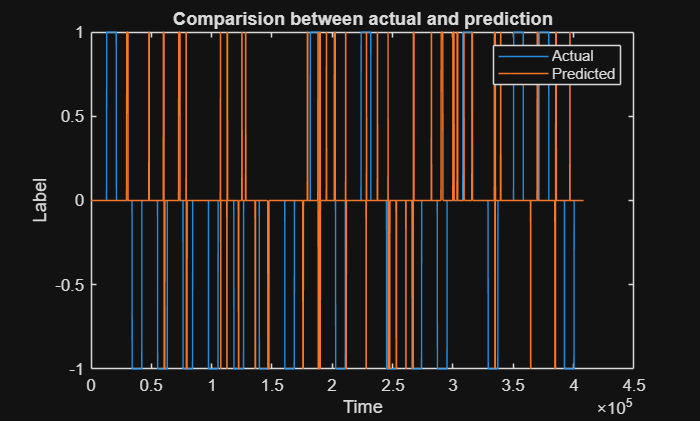

b1 = load("C:\Users\DELL\OneDrive\Desktop\BCI\experiment_data (4).txt");
T = readtable("test_predictions_fbcsp.csv");
figure;
plot(b1);
hold on;
plot(T{:,3});
hold off;
xlabel("Time");
ylabel("Label");
legend("Actual","Predicted");
title("Comparision between actual and prediction");

accu = sum(T{:,3} == b1(1:length(T{:,3})));
acc_per = accu*100/length(T{:,3})

acc_per = 61.0213

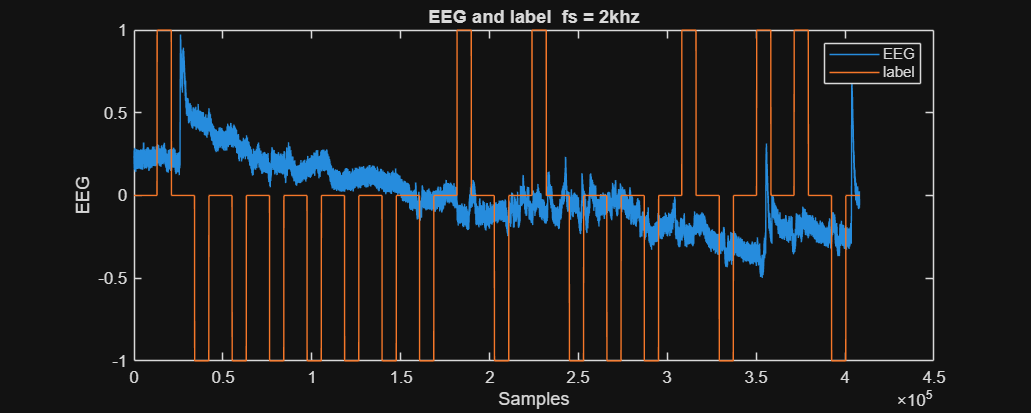


    a6 = load("D:\BCI_DSP\bci_testing\24_attempt5.txt");
    b6 = load("C:\Users\DELL\OneDrive\Desktop\BCI\experiment_data (4).txt");
    figure('Position',[400 400 1000 400]);

    plot(a6(:,2)-mean(a6(:,2)));
    hold on;
    plot(b6);
    hold off;
xlabel("Samples");
ylabel("EEG");
legend("EEG","label");
title("EEG and label  fs = 2khz");

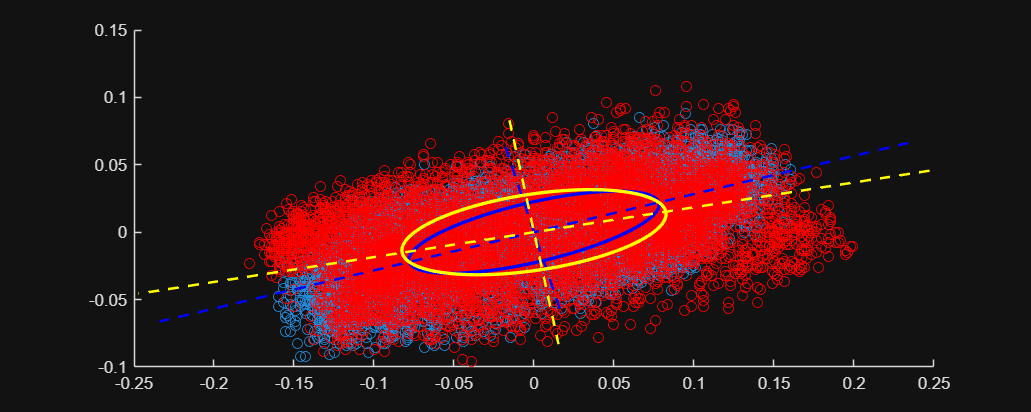

scatter(a6(12099:21048,1) - mean(a6(12099:21048,1)),a6(12099:21048,2)- mean(a6(12099:21048,2)));
hold on;
scatter(a6(34114:42148,1)-mean(a6(34114:42148,1)),a6(34114:42148,2)-mean(a6(34114:42148,2)),'r');
hold on;
draw_ellipse_and_axes(a6(12099:21048,:), 'b');
hold on;
draw_ellipse_and_axes(a6(34114:42148,:), 'y');

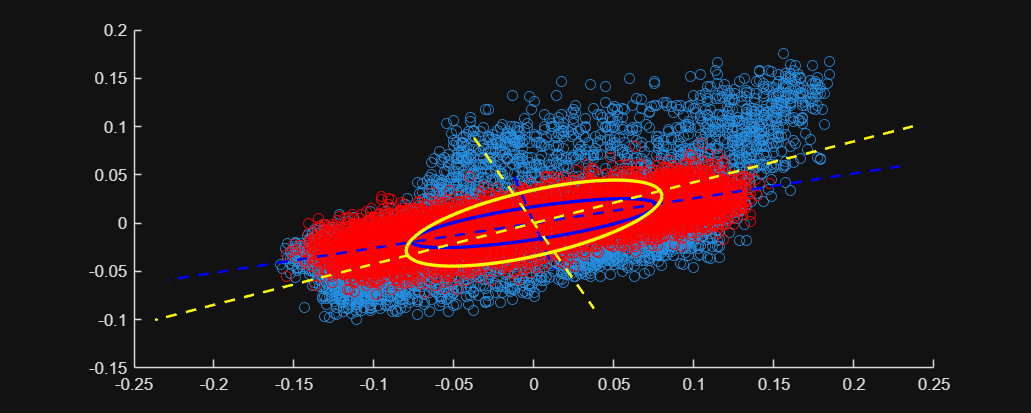

figure('Position',[400 400 1000 400]);
scatter(a6(181711:189745,1) - mean(a6(181711:189745,1)),a6(181711:189745,2)- mean(a6(181711:189745,2)));
hold on;
scatter(a6(139545:147580,1)-mean(a6(139545:147580,1)),a6(139545:147580,2)-mean(a6(139545:147580,2)),'r');
hold on;
function draw_ellipse_and_axes(X, color)
    mu = mean(X);
    C = cov(X - mu);
    [V, D] = eig(C);

    t = linspace(0, 2*pi, 100);
    circle = [cos(t); sin(t)];
    ellipse = V * sqrt(D) * circle;

    ellipse(1,:) = ellipse(1,:)  ;
    ellipse(2,:) = ellipse(2,:) ;
    plot(ellipse(1,:), ellipse(2,:), color, 'LineWidth', 2); hold on;

    scale = 3;
    for i = 1:2
        vec = V(:,i) * sqrt(D(i,i)) * scale;
        line([-vec(1), +vec(1)], ...
             [-vec(2), +vec(2)], ...
             'LineStyle','--','Color',color,'LineWidth',1.5);
    end
end
draw_ellipse_and_axes(a6(139545:147580,:), 'b');
hold on;
draw_ellipse_and_axes(a6(181711:189745,:), 'y');

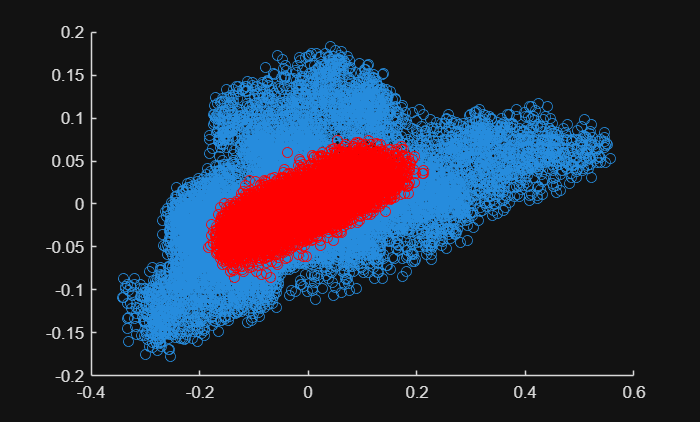

a =  12099:12099+8034;
b = 34114:42148;

aa = 139545:147579;
bb = 181711:189745;

aaa = 252958:266011;
bbb = 126480:139545-12;
%eeg_fb = apply_filter_bank(A_centered, 2000, FB_BANDS, BP_ORDER);

% A_centered1 = a6(139545:147579,:) - mean(a6(139545:147579,:));
% B_centered1 = a6(181711:189745,:) - mean(a6(181711:189745,:));
A_centered = a6(aaa,:) ;
B_centered = a6(bbb,:) ;

% A_centered = apply_filter_bank(A_centered1, 2000, [8,24], 8);
% B_centered = apply_filter_bank(B_centered1, 2000, [8,24], 8);

A_centered = A_centered - mean(A_centered);
B_centered = B_centered - mean(B_centered);

figure;
scatter(A_centered(:,1),A_centered(:,2));
hold on;
scatter(B_centered(:,1),B_centered(:,2),'r');
hold on;

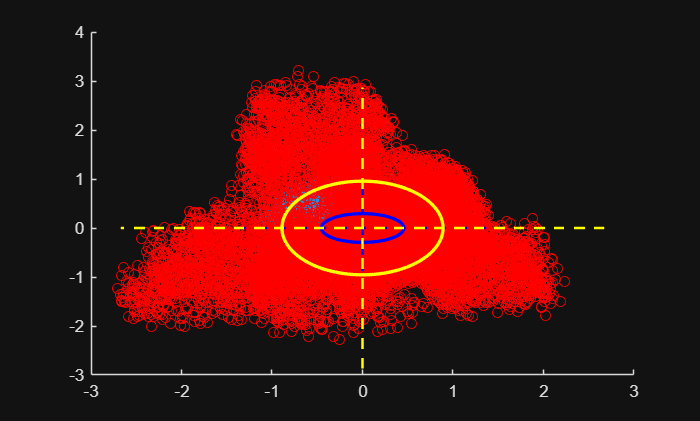

cov_A = (A_centered' * A_centered) / (length(A_centered(:,1)) - 1);
cov_B = (B_centered' * B_centered) / (length(B_centered(:,1))  - 1);

% --- STEP 3: Solve CSP ---
[V, D] = eig(cov_A, cov_A + cov_B);

% Sort eigenvalues and eigenvectors
[~, idx] = sort(diag(D), 'ascend');
W = V(:, idx); % The Spatial Filter Matrix (2 x 2)

% --- STEP 4: Apply the Filter ---
% To project the data: Z = X * W
proj_A = A_centered * W;
proj_B = B_centered * W;
figure;
scatter(proj_B(:,1),proj_B(:,2));
hold on;
scatter(proj_A(:,1),proj_A(:,2),'r');
hold on;
draw_ellipse_and_axes(proj_B , 'b');
hold on;
draw_ellipse_and_axes(proj_A, 'y');

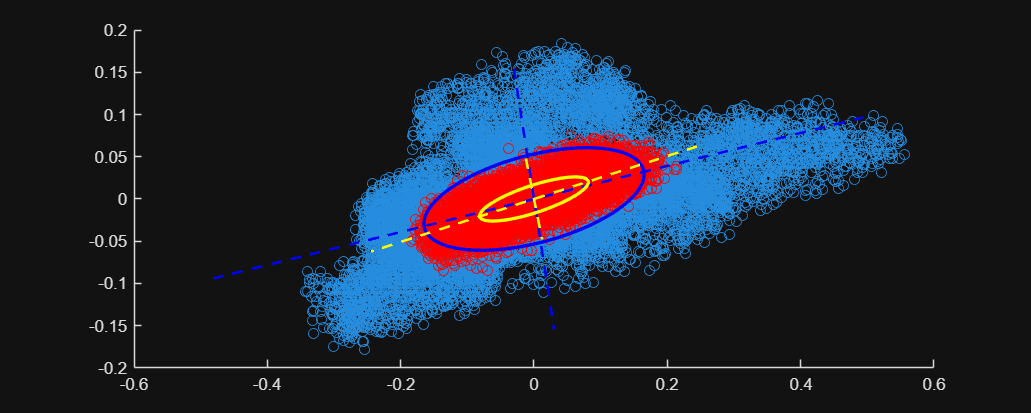

figure('Position',[400 400 1000 400]);
scatter(a6(252958:266011,1) - mean(a6(252958:266011,1)),a6(252958:266011,2)- mean(a6(252958:266011,2)));
hold on;
scatter(a6(126480:139545,1)-mean(a6(126480:139545,1)),a6(126480:139545,2)-mean(a6(126480:139545,2)),'r');
hold on;
draw_ellipse_and_axes(a6(252958:266011,:) , 'b');
hold on;
draw_ellipse_and_axes(a6(126480:139545,:), 'y');